# 離散空間での経路計画

## A*アルゴリズム

function [xg, yg] = calc_grid_index(position, cell_size)
% 連続座標 position=[x,y] をセルインデックスに丸める
xg = round(position(1)/cell_size);
yg = round(position(2)/cell_size);
end

function cm = CostMap(obstacles, field_size, cell_size)
% obstacle_position: Nx2（連続座標の障害物点）
% field_size: [xmin xmax ymin ymax]
% cell_size: セル幅
cm.obstacle_position = obstacles;
cm.cell_size = cell_size;
cm.field_size = field_size;

cm.w = round((field_size(2)-field_size(1))/cell_size);
cm.h = round((field_size(4)-field_size(3))/cell_size);
cm.map_matrix = zeros(cm.w+1, cm.h+1);

% 各障害点が属するセルを 1 に
for i = 1:size(obstacles,1)
    [gx, gy] = calc_grid_index(obstacles(i,:), cell_size);
    % 範囲チェック（はみ出した点は無視）
    if gx >= 0 && gx <= cm.w && gy >= 0 && gy <= cm.h
        cm.map_matrix(gx+1, gy+1) = 1;  % 1始まりで格納
    end
end
end

function car = DubinCar(dr, wr, r, delta_theta, cell_size)
% 構造体で Python のクラス相当を表現
car.dr = dr;
car.wr = wr;
car.r  = r;
car.delta_theta = delta_theta;
car.cell_size   = cell_size;
car.Dd = floor(dr/cell_size) + 1;
car.Dw = floor(wr/cell_size) + 1;
end

function next_poses = car_calc_next_poses(car, current_pose)
% 直進, 右旋回, 左旋回の 3 候補を返す
x = current_pose(1); 
y = current_pose(2); 
th = current_pose(3);
r  = car.r; 
dt = car.delta_theta;

xf = [ x + r*dt*cos(th), y + r*dt*sin(th), th ];

xl = [ x - r*sin(th) + r*sin(th + dt), ...
        y + r*cos(th) - r*cos(th + dt), ...
        th + dt ];

%--------------- 55行を修正 -------------------------%
xr = [ x + r*sin(th) - r*sin(th - dt), ...
        y - r*cos(th) + r*cos(th - dt), ...
        th - dt ];
%--------------- 55行を修正 -------------------------%

next_poses = [xl; xf; xr];
end

function safe = car_eval_safety(car, cm, pose)
% 車の外形（dr×wr の長方形）を回転・平行移動し、内部サンプリング点を
% グリッド衝突判定する
N = 10;          % サンプル分割数
% 長方形ローカル座標のサンプリング点（中心0）
xs = linspace(-car.dr/2, car.dr/2, N);
ys = linspace(-car.wr/2, car.wr/2, N);
[Xs, Ys] = meshgrid(xs, ys);
pts = [Xs(:), Ys(:)];  % Nx2

R = [cos(pose(3)) -sin(pose(3)); sin(pose(3)) cos(pose(3))];

% 回転・平行移動
world = (R * pts.').';
world(:,1) = world(:,1) + pose(1);
world(:,2) = world(:,2) + pose(2);

% 各点のセルインデックスに変換して衝突判定
for k = 1:size(world,1)
    [gx, gy] = calc_grid_index(world(k,:), car.cell_size);
    % 境界外
    if gx < 0 || gx > cm.w || gy < 0 || gy > cm.h
        safe = false; return
    end
    % 障害セル
    if cm.map_matrix(gx+1, gy+1) == 1
        safe = false; return
    end
end
safe = true;
end

function path = hybrid_astar(cost_map, car, start_pose, end_pose, tolerance)
% Python 実装に忠実な A* 探索（連続姿勢 + グリッド衝突判定）
if nargin < 5, tolerance = 0.1; end

% ノード（構造体配列）: parent, position[x y th], g,h,f
make_node = @(parent_idx, pos, g, h, f) struct( ...
    'parent', parent_idx, 'position', pos, 'g', g, 'h', h, 'f', f);

nodes = repmat(make_node(0,[0 0 0],0,0,0), 0, 1);
nodes(1) = make_node(0, start_pose, 0, 0, 0);

open   = 1;   % オープンリスト：nodes のインデックス
closed = [];  % クローズド

count = 0; 
iter_max = 1000;
while count < iter_max && ~isempty(open)
    % f 最小を選択
    [~, imin] = min([nodes(open).f]);
    current_idx = open(imin);
    open(imin) = [];
    closed(end+1) = current_idx; 
    
    cur = nodes(current_idx).position;
    
    % ゴール判定
    err = abs(cur(1) - end_pose(1)) ...
        + abs(cur(2) - end_pose(2)) ...
        + (1 - cos(cur(3) - end_pose(3)));
    if err <= tolerance
        % 復元
        path = [];
        idx = current_idx;
        while idx ~= 0
            path = [nodes(idx).position; path];
            idx = nodes(idx).parent;
        end
        fprintf('最適経路は ['); fprintf('(%g,%g,%g) ', path.'); fprintf('] です．\n');
        return
    end
    
    % 子ノード生成（候補姿勢）
    next_poses = car_calc_next_poses(car, cur);
    children = [];
    for i = 1:size(next_poses,1)
        if car_eval_safety(car, cost_map, next_poses(i,:))
            children = [children; next_poses(i,:)]; 
        end
    end
    
    % 各子の G,H,F を計算
    for i = 1:size(children,1)
        child_pos = children(i,:);
        
        % 既にクローズに「完全一致」姿勢があればスキップ
        if any(arrayfun(@(idx) all(nodes(idx).position == child_pos), closed))
            continue
        end
        
        G = nodes(current_idx).g + car.r * car.delta_theta; % Python準拠
        H = abs(child_pos(1) - end_pose(1)) ...
          + abs(child_pos(2) - end_pose(2)) ...
          + (1 - cos(child_pos(3) - end_pose(3)));
        F = G + H;
        
        % オープンに同一姿勢があり、自分の g が劣るならスキップ
        worse = false;
        for ok = 1:numel(open)
            on = nodes(open(ok));
            if all(child_pos == on.position) && (G > on.g)
                worse = true; break
            end
        end
        if worse, continue, end
        
        % 追加
        nodes(end+1) = make_node(current_idx, child_pos, G, H, F);
        open(end+1)  = numel(nodes); 
    end
    
    count = count + 1;
end

fprintf('最適経路は見つかりませんでした！\n');
path = [];
end

## 結果の表示

function plot_map_and_path(cm, car, path, start_pose, end_pose)
if nargin < 3, path = []; end

cell_size = cm.cell_size;
cells = cm.obstacle_position;

figure; 
ax = gca; 
hold(ax,'on');

% 障害セルを黒で塗る（各点が属するセルを塗る）
for k = 1:size(cells,1)
    x = cells(k,1); y = cells(k,2);
    % セルの左下隅
    cx = round(x/cell_size)*cell_size - cell_size/2;
    cy = round(y/cell_size)*cell_size - cell_size/2;
    rectangle('Position',[cx, cy, cell_size, cell_size], ...
              'FaceColor','k','EdgeColor','k','LineWidth',1);
end

% パス矩形（回転描画）
if ~isempty(path)
    for i = 1:size(path,1)
        draw_rotated_rect(ax, path(i,1), path(i,2), path(i,3), car.dr, car.wr, ...
                          [65 105 225]/255, [0 0 0.5], 0.6); 
    end
end

% 始点・終点の枠（姿勢つき）
draw_rotated_rect(ax, start_pose(1), start_pose(2), start_pose(3), car.dr, car.wr, ...
                  'none', [0 0.6 0], 1.0, 2.0);
draw_rotated_rect(ax, end_pose(1),   end_pose(2),   end_pose(3),   car.dr, car.wr, ...
                  'none', [0.85 0 0], 1.0, 2.0);

% 軸設定
axis equal; 
box on;
grid on
xlim([cm.field_size(1), cm.field_size(2)]);
ylim([cm.field_size(3), cm.field_size(4)]);
xlabel('x'); 
ylabel('y');
fontsize(16, 'points');
hold(ax,'off');
end

function draw_rotated_rect(ax, x, y, theta, dx, dy, faceColor, edgeColor, alphaVal, lineWidth)
% 中心 (x,y)，角度 theta の長方形（dx×dy）をパッチで描画
if nargin < 9, alphaVal = 0.6; end
if nargin < 10, lineWidth = 1.0; end

hx = dx/2; hy = dy/2;
% 中心基準の4頂点（左下→左上→右上→右下）
pts = [-hx -hy;
       -hx  hy;
        hx  hy;
        hx -hy];
R = [cos(theta) -sin(theta); sin(theta) cos(theta)];
pR = (R * pts.').';
pR(:,1) = pR(:,1) + x;
pR(:,2) = pR(:,2) + y;

patch('XData',pR(:,1),'YData',pR(:,2), ...
      'FaceColor',faceColor,'EdgeColor',edgeColor, ...
      'FaceAlpha',alphaVal,'LineWidth',lineWidth,'Parent',ax);
end

## 実行

field_size = [0, 5, 0, 5];        % [xmin, xmax, ymin, ymax]
start      = [1.0, 1.0, pi/2];    % [x, y, theta]
goal       = [4.5, 4.5, pi/2];    % [x, y, theta]
cell_size  = 0.2;

% 各点が属するグリッドに障害物を配置
obs1 = [0:cell_size:3.8; 3*ones(1,20)]';
obs2 = [2:cell_size:5; 2*ones(1,16)]';
obs3 = [3.8*ones(1,6); 3:cell_size:4]';
obstacles = [obs1; obs2; obs3];

% 車両パラメータ（Python と対応）
dr = 0.7;            % 車の長さ方向サイズ
wr = 0.2;            % 車の幅方向サイズ
r  = 1.0;            % 旋回半径
delta_theta = pi/6;  % 1ステップの回転角
tolerance   = 0.1;   % ゴール判定誤差

% マップ生成
cost_map = CostMap(obstacles, field_size, cell_size);
disp("障害物一覧（[x y]）:");

障害物一覧（[x y]）:


disp(cost_map.obstacle_position);

         0    3.0000
    0.2000    3.0000
    0.4000    3.0000
    0.6000    3.0000
    0.8000    3.0000
    1.0000    3.0000
    1.2000    3.0000
    1.4000    3.0000
    1.6000    3.0000
    1.8000    3.0000
    2.0000    3.0000
    2.2000    3.0000
    2.4000    3.0000
    2.6000    3.0000
    2.8000    3.0000
    3.0000    3.0000
    3.2000    3.0000
    3.4000    3.0000
    3.6000    3.0000
    3.8000    3.0000
    2.0000    2.0000
    2.2000    2.0000
    2.4000    2.0000
    2.6000    2.0000
    2.8000    2.0000
    3.0000    2.0000
    3.2000    2.0000
    3.4000    2.0000
    3.6000    2.0000
    3.8000    2.0000
    4.0000    2.0000
    4.2000    2.0000
    4.4000    2.0000
    4.6000    2.0000
    4.8000    2.0000
    5.0000    2.0000
    3.8000    3.0000
    3.8000    3.2000
    3.8000    3.4000
    3.8000    3.6000
    3.8000    3.8000
    3.8000    4.0000




% 車両モデル
car = DubinCar(dr, wr, r, delta_theta, cell_size);

% 探索
path = hybrid_astar(cost_map, car, start, goal, tolerance);

最適経路は [(1,1,1.5708) (1.13397,1.5,1.0472) (1.5,1.86603,0.523599) (1.86603,2.23205,1.0472) (2.23205,2.59808,0.523599) (2.73205,2.73205,2.22045e-16) (3.23205,2.59808,-0.523599) (3.73205,2.4641,2.22045e-16) (4.23205,2.59808,0.523599) (4.59808,2.9641,1.0472) (4.73205,3.4641,1.5708) (4.59808,3.9641,2.0944) (4.4641,4.4641,1.5708) ] です．


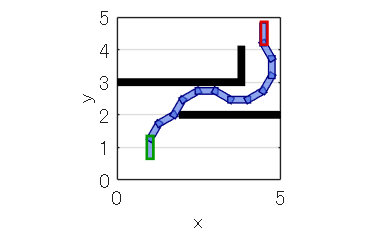


% 結果の表示
plot_map_and_path(cost_map, car, path, start, goal);